# **Tutorial 10**: on-board angular momentum  ( $\approx 2\;mn$ run).

*by D. Alazard and F. Sanfedino - ISAE-SUPAERO*

## 1. Description

This tutorial aims to show how on-board angular monentums can be taken into account in a SIMULINK model based on the `SDTlib`. Indeed the gyroscopic stiffness due to an on-board angular momentum is a linear term which can be modelled thanks to the block `One-port angular momentum` or the block` Reaction Wheel` of the `sub-library 6 dof bodies`. 

Let is consider a wheel $\mathcal W$ with an inertia $I_w$, spinning at the angular rate $\Omega$ arount the axis $\mathbf z_w$ in the inherit frame $\mathcal R_a$ i.e. the frame of the parent body carrying the wheel at the point $P$. The direction of $\mathbf z_w$ in $\mathcal R_a$ is defined by the azimuth $\alpha$ and the elevation $\beta$ angles:

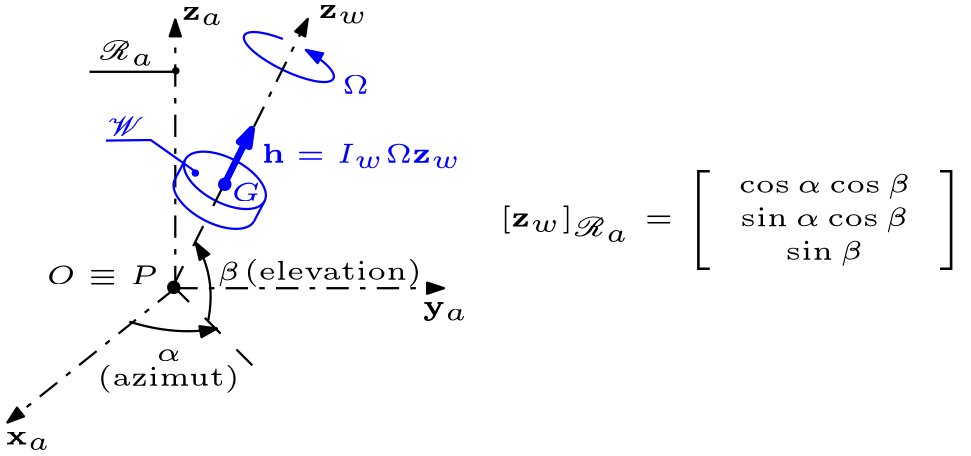

Assuming that the wheel is **balanced** , the angular rate $\Omega$ is constant and the wheel axis $\mathbf z_w$ is constant in $\mathcal R_a$, it is thus possible to derive the $6\times 6$**direct dynamic model **$[\mathbf M^{\mathcal W}_P]_{\mathcal R_a}(\mathrm s)$ of the spining wheel system $\mathcal W$ at the connection point $P$ and projected in the inherit frame $\mathcal R_a$. This model is detailled in the inline help of the block `One-port angular momentum:`

web DocMomentum.html -new

This model is the transfer from the [motion vector](matlab:open('../SDTfct/doc_SDTlib/doc_BODIES/doc_hub/DocGeneralNotations.html')) $[\delta\mathbf m^{\mathcal B}_{P}]_{\mathcal R_a}$ (18 components = 6 DoFs accelerations , 6 DoFs velocities and 6 DoFs positions), of the parent body $\mathcal B$ at the point $P$ to the interaction wrench $\mathbf W_{./\mathcal W,P$ applied by the parent body to $\mathcal W$ at point $P$. Thus it possible to describe the interconnection with the parent body by a feedback loop on a block-diagram representation exactly as it was already done for rigid or flexible appendages (see also tutorial 1: [***Introduction***](matlab:open('../Tutorial1/tutorial1.html'))). If the parent body is the base body $\mathcal B$, thus $\mathcal R_a=\mathcal R_b$ and the  model of the base holding the wheel is:

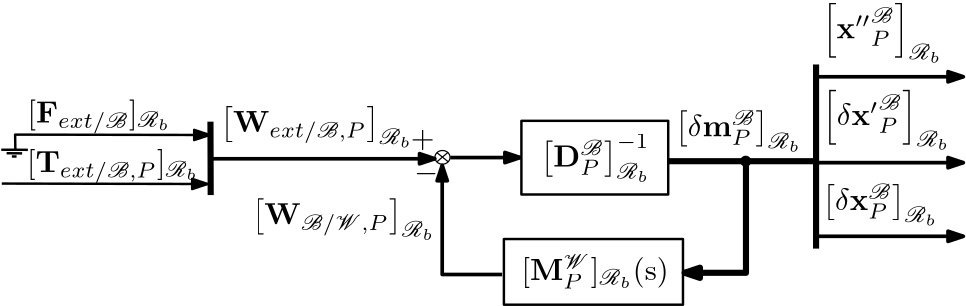

## 2. Single on-board angular momentum

A rigid body $\mathcal B$ holding a spinning wheel $\mathcal W$ along it $\mathbf z$ axis ($\mathbf z_w=\mathbf z_b$) is considered.  The model `G` of the whole system from the 3 components of the external torque $[\mathbf T_{ext/\mathcal B,P_1}]_{\mathcal R_b}$ applied to $\mathcal B$at the point $P_1$ (here the reference point of $\mathcal B$) to its angular rate $[\mathbf \omega]_{\mathcal R_b}$ is described by the SIMULINK model `SingleWheel.slx` involving a` multi-port rigid body` block and  a `One-port angular momentum `block (in yellow). The dialob box of this block is also depicted in the following Figure.

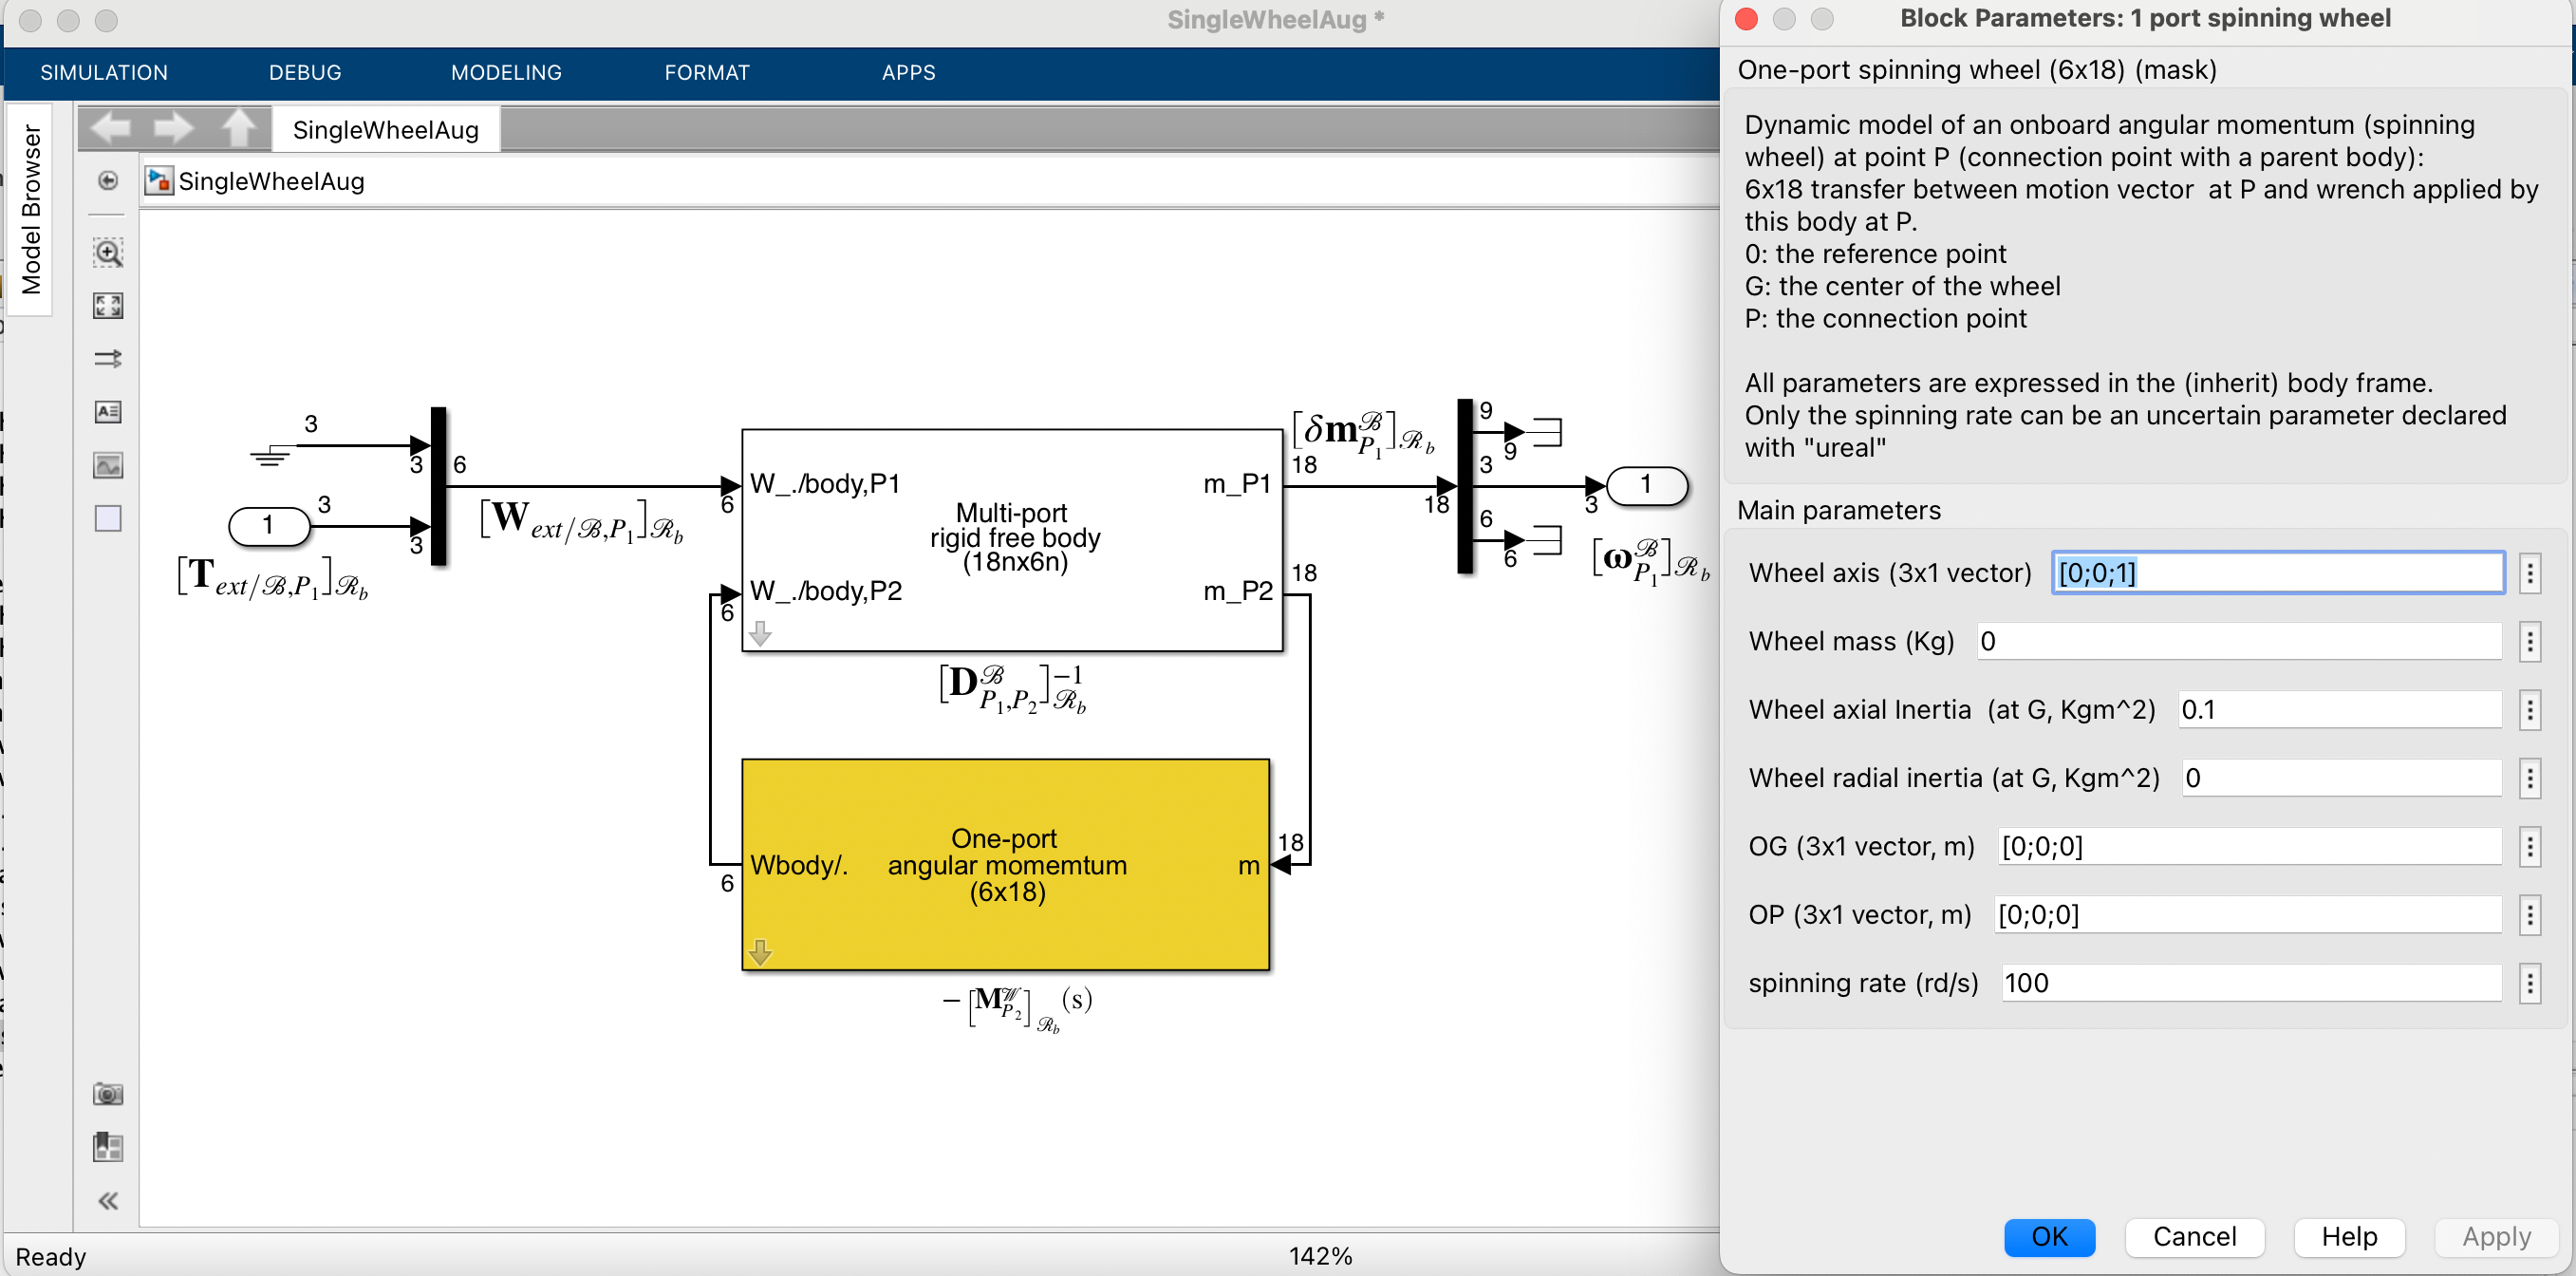

The model directly derived from this SIMULINK model:

SingleWheelAug
G=linearize('SingleWheelAug');

One can check that the model `G` have 3 states and thus 3 eigenvalues with:

-  a pair of auto-conjugate complex eigenvalues due to the gyroscopic mode,

- one integrator rellative to the angular dynamics around the spin axis.

damp(G)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00                -1.00e+00       0.00e+00              Inf    
 -2.17e-19 + 1.83e-01i     1.19e-18       1.83e-01         4.61e+18    
 -2.17e-19 - 1.83e-01i     1.19e-18       1.83e-01         4.61e+18    


The frequency-domain response of `G`:

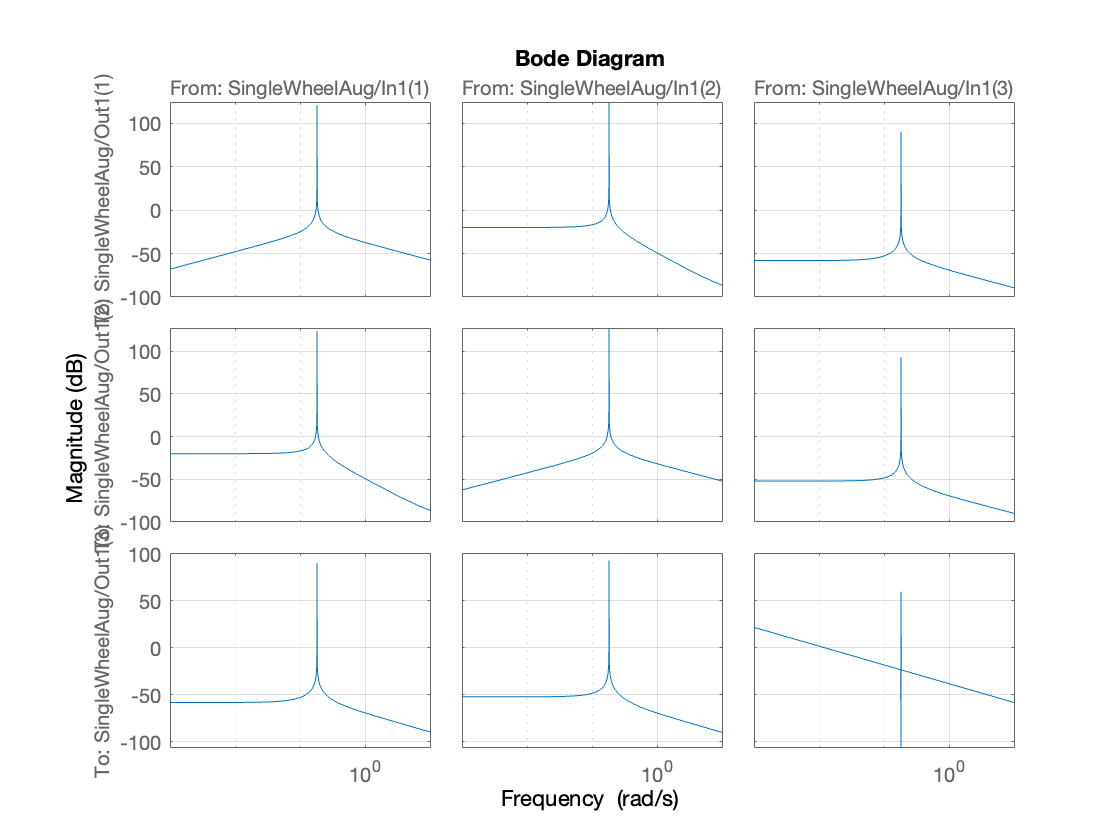

figure
bodemag(G,{0.001 10})
grid

Since the angular momentum is along the $\mathbf z$-axis of the main body, one can check:

-  the gyroscopic stiffness on $\mathbf x$ and $\mathbf y$ axes and the resonnance due to the gyroscopic mode (at $\omega_{gy}=0.183\,rad/s$. The distrubance rejection due to the gyroscopic effect is highlighted: a very low frequency torque (input) on $\mathbf x$ (resp. $\mathbf y$) axis does not create an angular rate around the $\mathbf x$(resp. $\mathbf y$) axis.

- this effect is not visible on the transfer around $\mathbf z$-axis (the angular momentum axis) which is thus free to move. This transfer exhibits a pole zero cancellation at $\mathrm s^2+\omega^2_{gy}$. Indeed:

zpk(G(3,3))

ans =
 
  From input "SingleWheelAug/In1(3)" to output "SingleWheelAug/Out1(3)":
  0.012497 (s^2 + 0.03334)
  ------------------------
     s (s^2 + 0.03338)
 
Continuous-time zero/pole/gain model.



## 3. Reaction wheels system

The spacecraft model studied in [***tutorial 2***](matlab:open('../Tutorial2/tutorial2.html')) is reconsidered with

- only one rotating SA (Solar Array): $\theta$ is geometric configuration of the SA w.r.t the main body $\mathcal B$,

- a reaction wheel systems (`RWS`) carried by the main body $\mathcal B$ at its center of mass $B.$

The reaction wheel system is composed of 4 reaction wheels in a pyramidal configuration described in the following Figure:

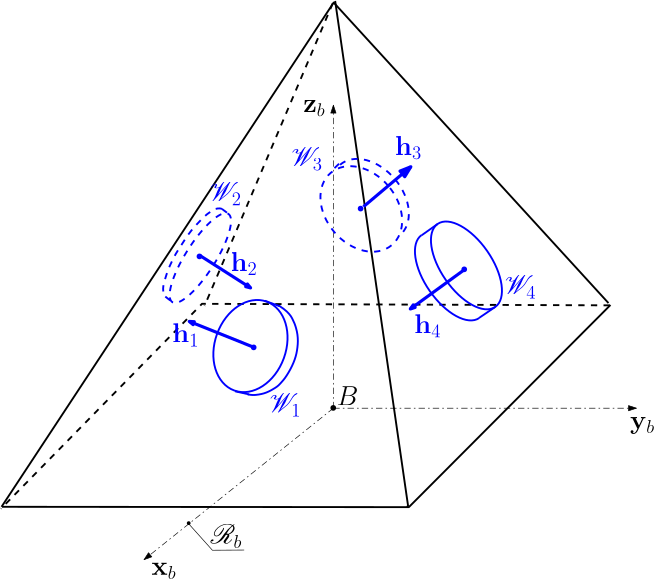

Each wheel has a maximal angular momentum of $100 \,Nms$ with a maximal spinning rate of $10000\,rpm$. The pyramid geometry (azimth $\alpha$ and elevation $\beta$ angles) is summarized in the following table:


$$\begin{array}{l | l | | |}  \;  & \mathcal W_1 &  \mathcal W_2 & \mathcal W_3 & \mathcal W_4 \\ \hline \alpha (deg) & 0 & 90 & 180 & -90 \\ \hline \beta (deg)  &45& -45 & 45 & -45  \\  \hline \end{array}$$


Note that if all the wheels are spinning at the same angular rate, the total angular momentum is null: $\Sigma_i \mathbf h_i=\mathbf 0$.

The objective is to build the $3\times 3$ model $\mathbf G(\mathrm s,\theta,\Omega_1,\Omega_2,\Omega_3,\Omega_4)$ of the whole system between the 3 component torque $[\mathbf T_{ext/\mathcal B,P_3}]_{\mathcal R_b}$ applied to the main body $\mathcal B$ at the point $P_3\equiv B$ (by the `RWS` itself or by orbital diistrurbances) and the main body angular rate $[\mathbf \omega^\mathcal B_{P_3}]_{\mathcal R_b}$, projected in the frame $\mathcal R_b$ and fully  parameterized according to the SA angular configuration $\theta$ and the 4 spinning rates $\Omega_i$, $i=1,2,3,4$ of the 4 wheels. Each of the $\Omega_i$ can vary between $\pm\;10000 \,rpm$, the nominal value being $0$.

To model such a reaction wheel systems with 4 reaction wheel subsystems,  it is recommanded to user a `massless connection body `block from the` 6 dof body` sub-library. See also:

web DocMassLessBody.html -new

Indeed this block allows to extend the number of connection ports of the `multi-port rigid body` block which is limited to 5. Then the reaction wheel system is decribed in the following Figure and is embedded in the subsystem `RWS`.

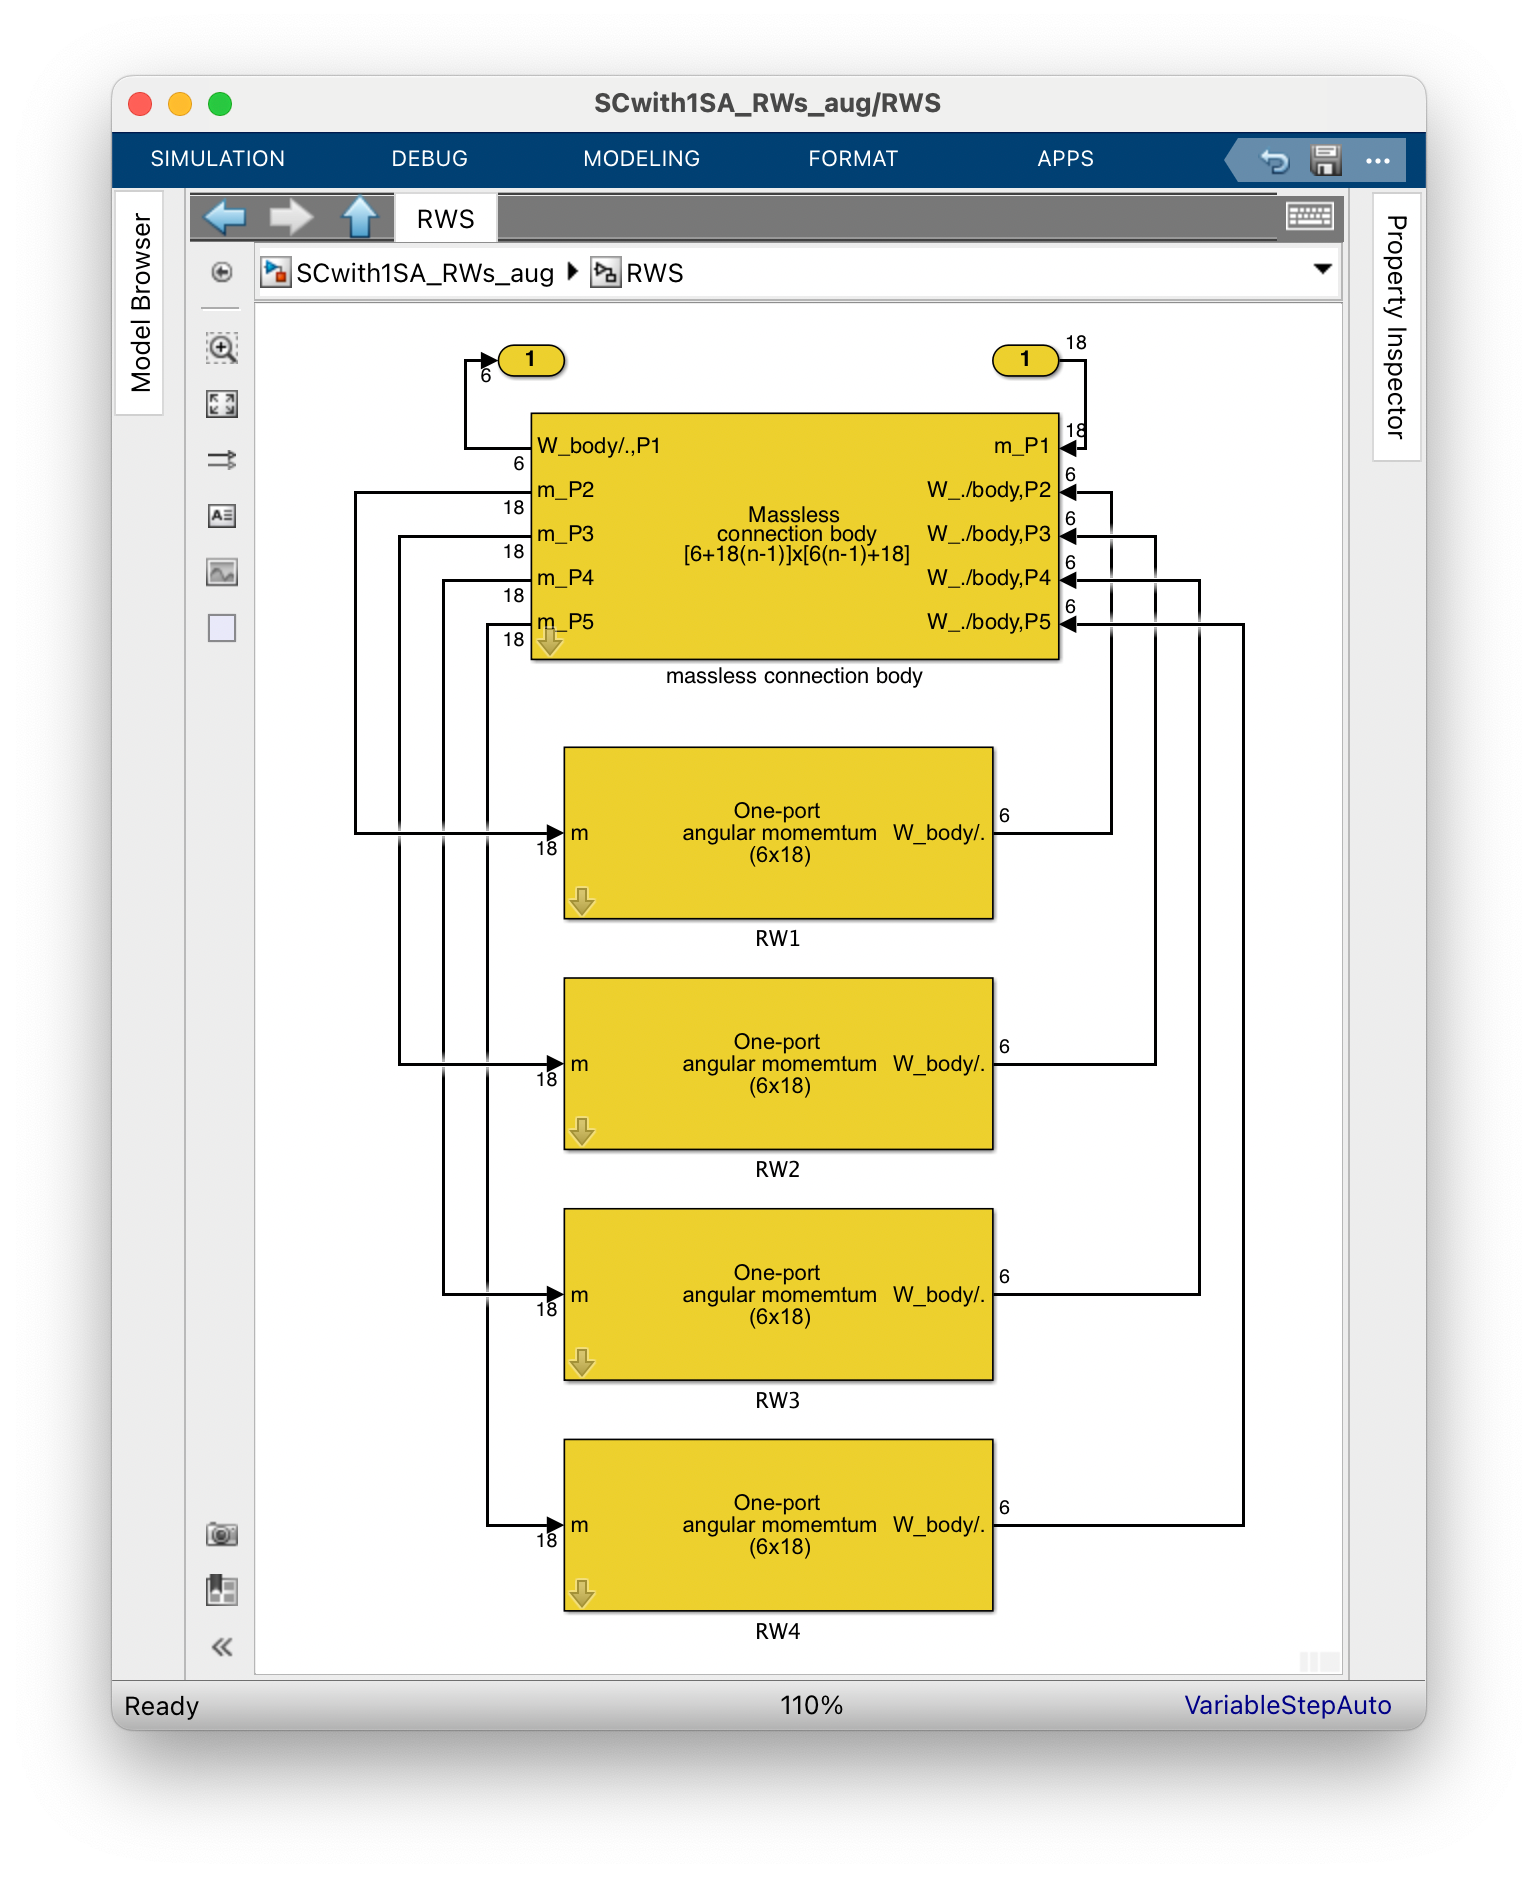

The subsystem `RWS` is then connected to the main body $\mathcal B$ like the other appendage (SA) in the SIMULINK file `SCwith1SA_RWs_aug.slx` (see next Figure).

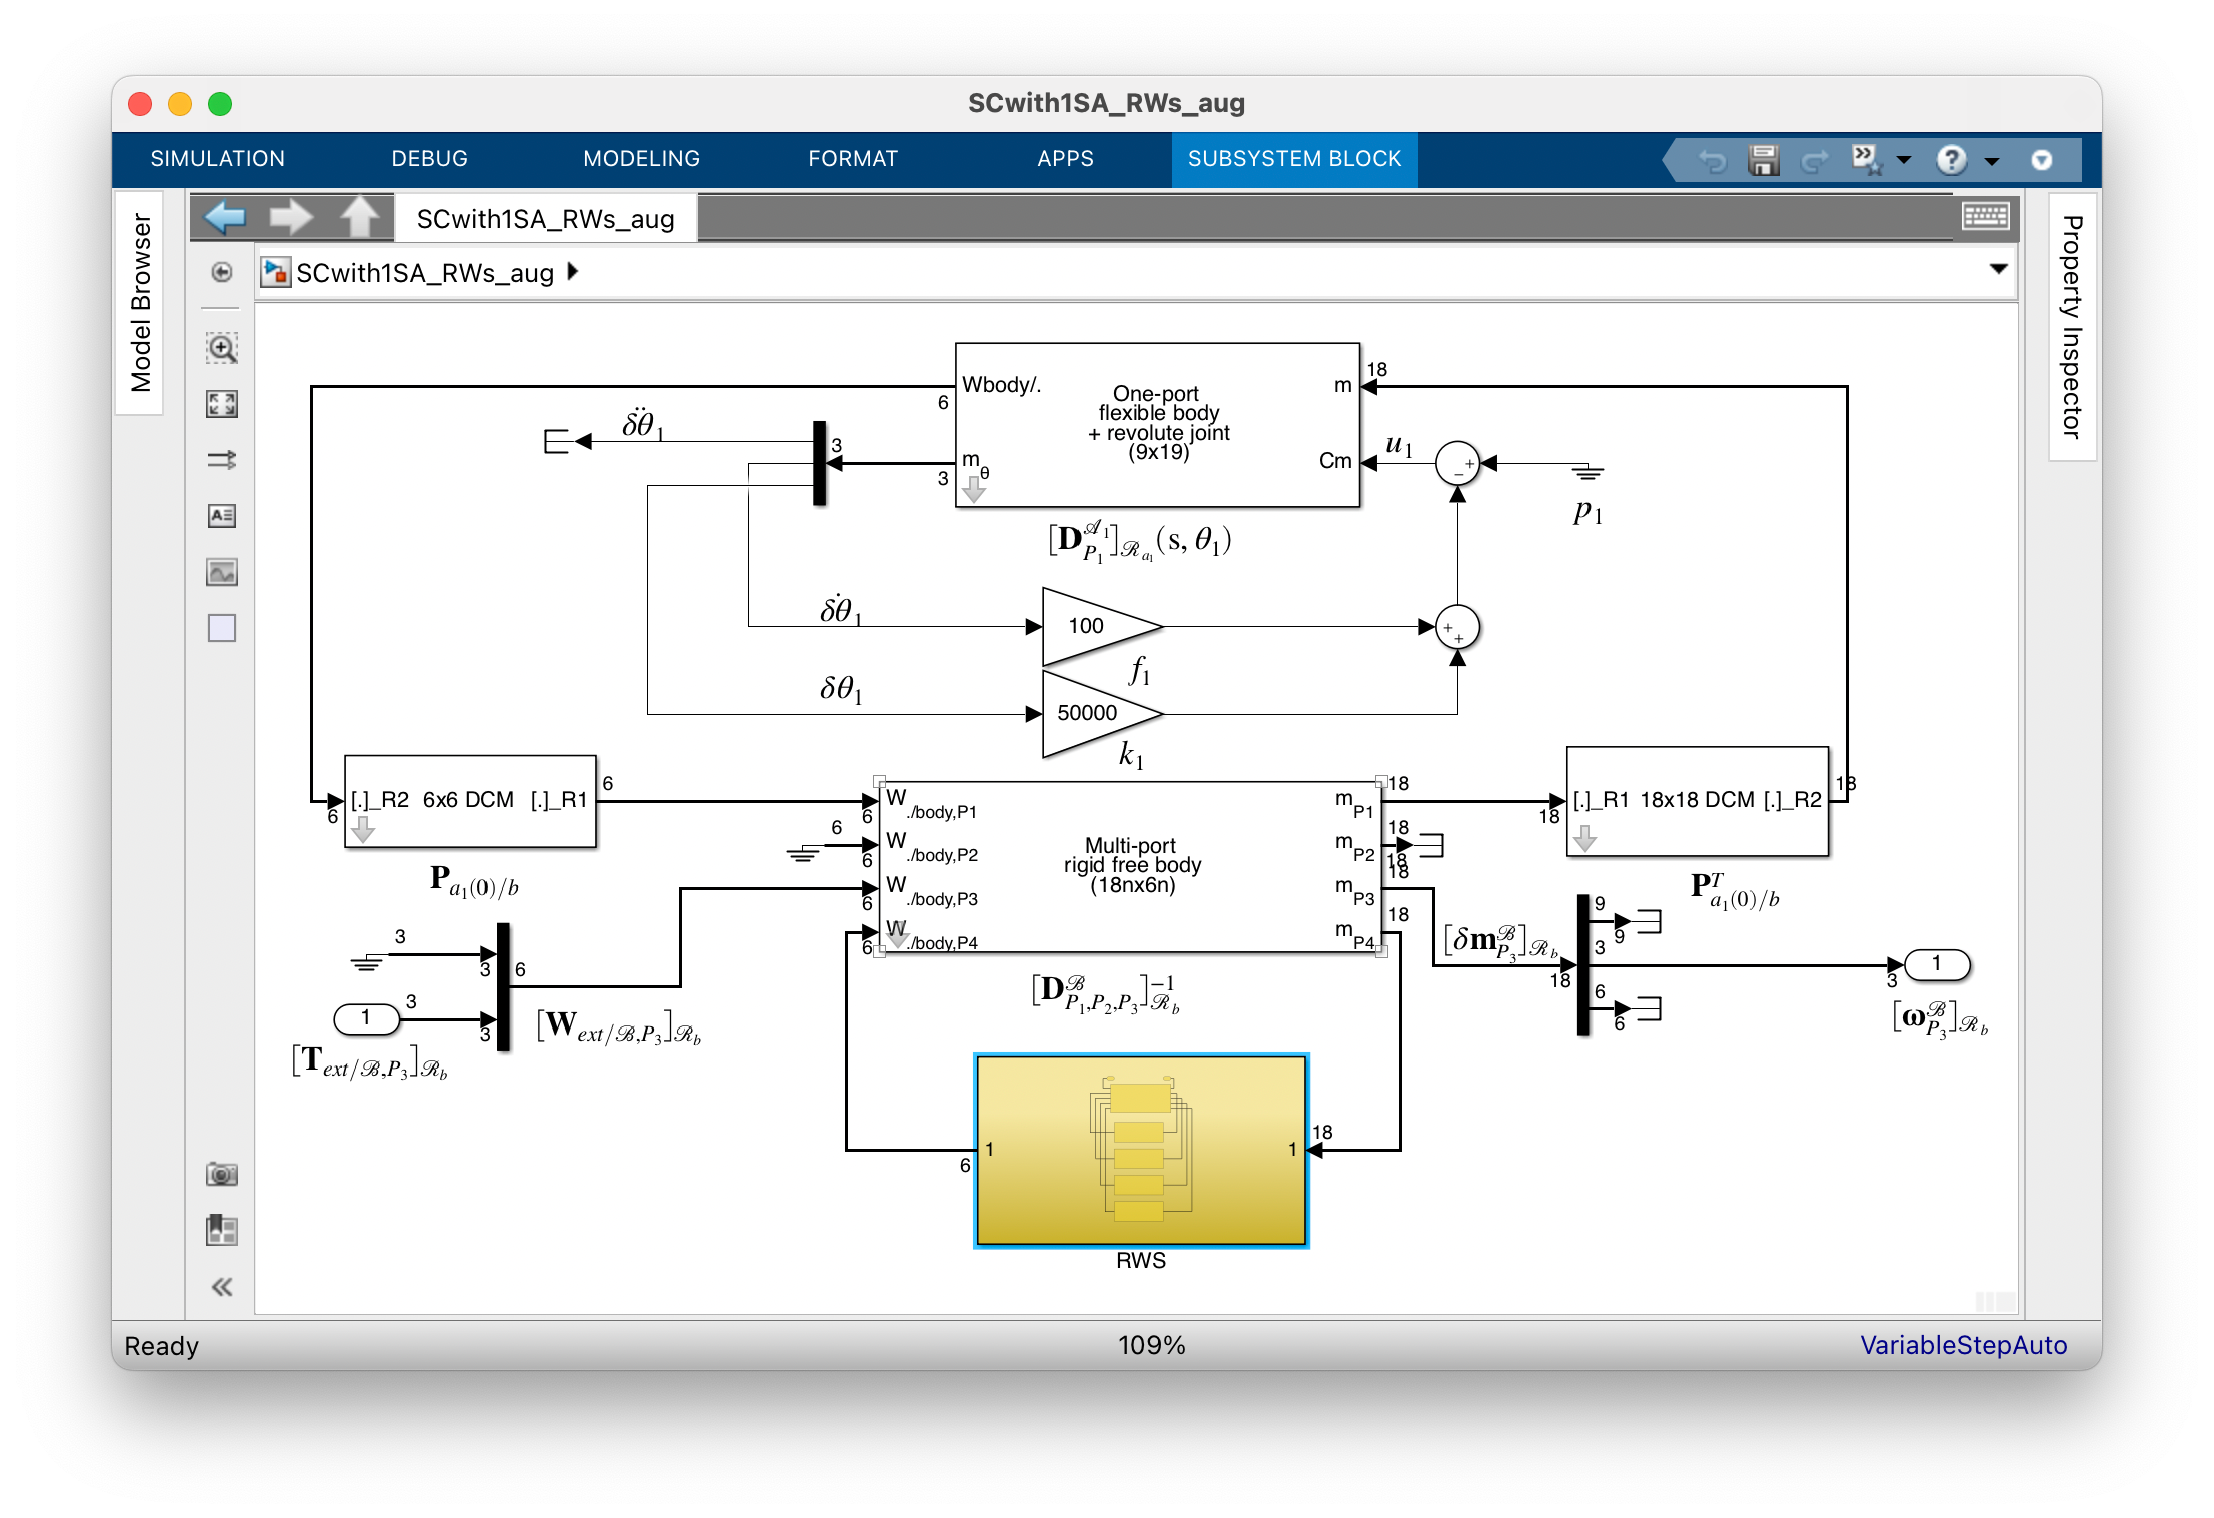

The data relative to the reaction wheel system:

wRW=20000*pi/60;                      % max spinning rate (10000 rpm in rad/s)
mRW=0;                                % Mass (Kg)   
IrRW=0;                               % Radial inertia (Kgm^2)
IwRW=100/wRW;                         % Axial inertia (Kgm^2) for a maximal momentum of 100 Nms
azimuthRW=[0 90 180 -90]*pi/180;      % the list of azimuht angles (rad)
elevationRW=[45 -45 45 -45]*pi/180;   % the list of elevations angles (rad)
wRW1=ureal('RW1',0,'PlusMinus',wRW);  % varying spinning rates (rad/s)
wRW2=ureal('RW2',0,'PlusMinus',wRW);
wRW3=ureal('RW3',0,'PlusMinus',wRW);
wRW4=ureal('RW4',0,'PlusMinus',wRW);

The model directly derived from this SIMULINK model:

% the whole model
SCwith1SA_RWs_aug
Gu=ulinearize('SCwith1SA_RWs_aug')

Gu =

  Uncertain continuous-time state-space model with 3 outputs, 3 inputs, 11 states.
  The model uncertainty consists of the following blocks:
    RW1: Uncertain real, nominal = 0, variability = [-1.05e+03,1.05e+03], 2 occurrences
    RW2: Uncertain real, nominal = 0, variability = [-1.05e+03,1.05e+03], 2 occurrences
    RW3: Uncertain real, nominal = 0, variability = [-1.05e+03,1.05e+03], 2 occurrences
    RW4: Uncertain real, nominal = 0, variability = [-1.05e+03,1.05e+03], 2 occurrences
    tan_Theta_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences

Type "Gu.NominalValue" to see the nominal value, "get(Gu)" to see all properties, and "Gu.Uncertainty" to interact with the uncertain elements.



The model have 11 state variables:

- 3 flexible modes for the solar array (thus 6 states),

- 1 mode for the mechanism between the main body and the solar array (2 states),

- 3 integrators between  $[\dot\mathbf \omega^\mathcal B_{P_3}]_{\mathcal R_b}$ and  $[\mathbf \omega^\mathcal B_{P_3}]_{\mathcal R_b}$ which are perturbed by gyroscopic stiffness when the wheel angular rates are non null.

This model depends on 5 varying parameters:` RW1`, `RW2`, `RW3`, `RW4:` the spinning rates of the wheels and` tan_Theta_div4` ( $\sigma_4=\tan(\theta/4)$ ): the angular configuration of the solar pannel.

damp(Gu)                      % poles of the system in the nominal configuration

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00                -1.00e+00       0.00e+00              Inf    
  0.00e+00                -1.00e+00       0.00e+00              Inf    
  0.00e+00                -1.00e+00       0.00e+00              Inf    
 -6.05e-02 + 8.24e+00i     7.34e-03       8.24e+00         1.65e+01    
 -6.05e-02 - 8.24e+00i     7.34e-03       8.24e+00         1.65e+01    
 -1.31e-01 + 1.99e+01i     6.60e-03       1.99e+01         7.61e+00    
 -1.31e-01 - 1.99e+01i     6.60e-03       1.99e+01         7.61e+00    
 -1.97e-01 + 3.71e+01i     5.32e-03       3.71e+01         5.07e+00    
 -1.97e-01 - 3.71e+01i     5.32e-03       3.71e+01         5.07e+00    
 -2.34e+01 + 1.57e+02i     1.47e-01       1.59e+02         4.27e

It is worth to mention that the computation of the minimal realization works on the parameter varying system i.e. for any value of the parametric configurations.

The frequency-domain response of $\mathbf G(\mathrm s,\theta,\Omega_1,\Omega_2,\Omega_3,\Omega_4)$:

figure
bodemag(usample(Gu,50),Gu.NominalValue,{0.01 100})
grid

The nominal model (red plot) does not exhibit  the low frequency resonance due to the gyroscopic stiffness (all the wheels are not spinning), one can check on the cross coupling terms that the gyrsocopic stiffness increases axis couplings (by an average level of +40db on the X-Y axis coupling)

On such an "over-actuated" platform, the frequency of the gyroscopic mode can reach approximatively $1\,rad/s$ !!

Indeed, on can plot the frequency domain response of the model for the maximal spinnning rates with the good sign (leading to the stiffest gyroscopic mode, yellow plot):

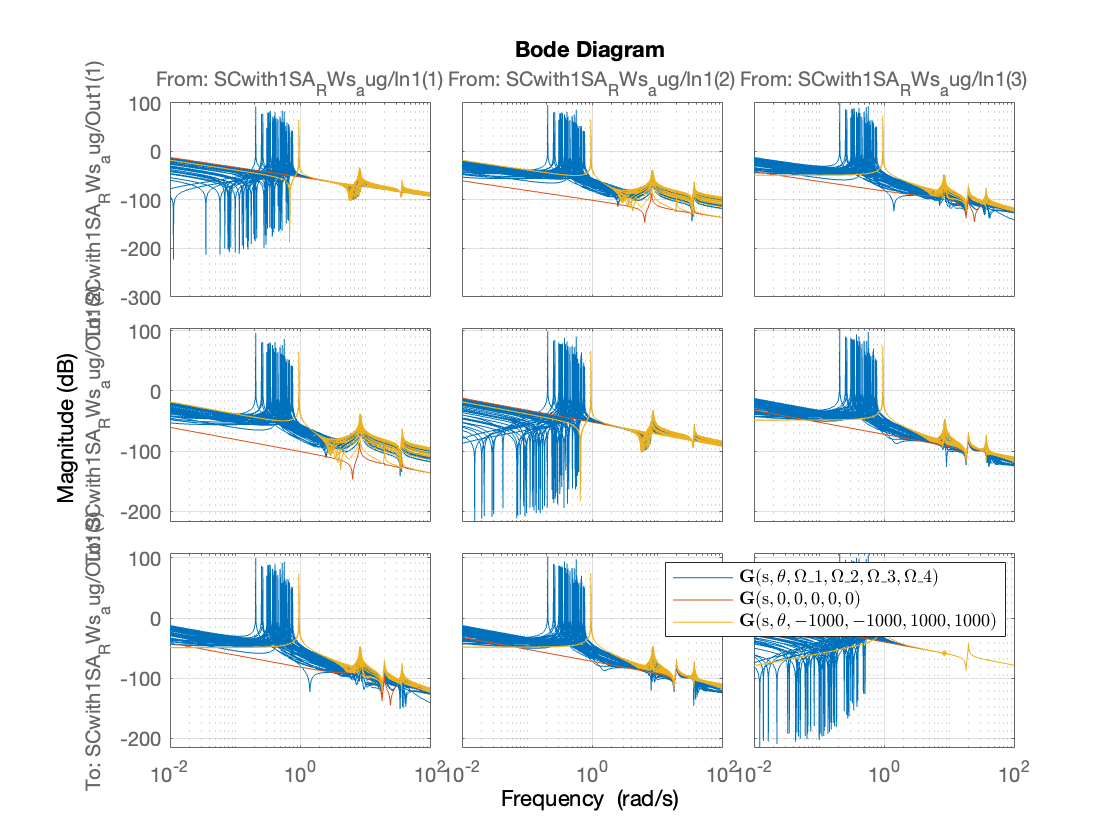

GuM=usubs(Gu,'RW1',-1000,'RW2',-1000,'RW3',1000,'RW4',1000);
hold on
bodemag(GuM,{0.01 100})
legend('$\mathbf G(\mathrm s,\theta,\Omega_1,\Omega_2,\Omega_3,\Omega_4)$',...
       '$\mathbf G(\mathrm s,0,0,0,0,0)$',...
       '$\mathbf G(\mathrm s,\theta,-1000,-1000,1000,1000)$','Interpreter','Latex')

Assuming that all the wheels have the same spinning rate (the wheel $\mathcal W_1$ ones), the gyroscopic effect vanishes due to the wheel pyramidal configuration:

Gu0=usubs(Gu,'RW2',wRW1,'RW3',wRW1,'RW4',wRW1);
Gu0=simplify(Gu0,'full') % still 2 occurences remaining due to numerical burden!!

Gu0 =

  Uncertain continuous-time state-space model with 3 outputs, 3 inputs, 11 states.
  The model uncertainty consists of the following blocks:
    tan_Theta_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences

Type "Gu0.NominalValue" to see the nominal value, "get(Gu0)" to see all properties, and "Gu0.Uncertainty" to interact with the uncertain elements.



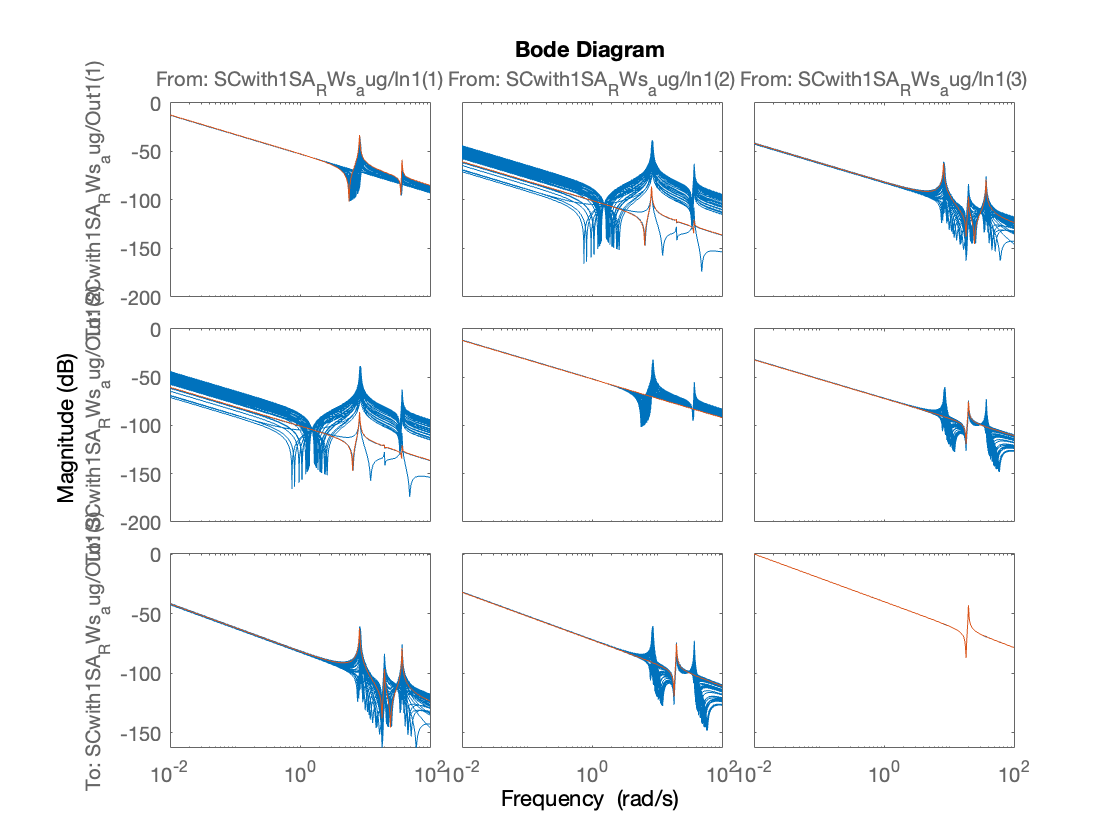

figure
bodemag(usample(Gu0,50),Gu.NominalValue,{0.01 100})

## 4. Remark

If the wheel is carried by a revolute joint around an axis orthogonal to $\mathbf z_w$ (also called precession axis), it is also possible to model a CMG (Control Moment Gyro). In that case, the obtained linear model is only valid for small variations of the precession angle which is considered as a geometric configuration variable. But is possible to derive a linear model  of a platform actuated by a cluster of CMGs, parameterized according to the precession angles.